# Метод главных компонент

Создаем 2-х мерный вектор

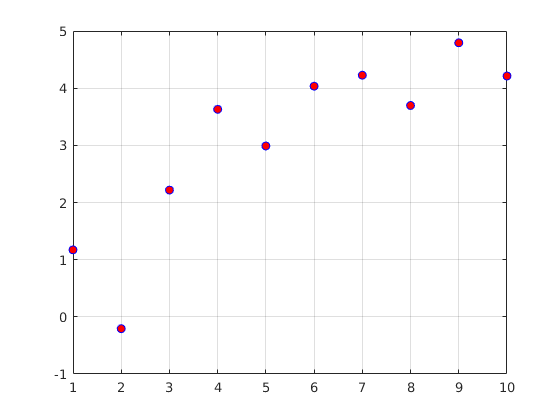

t = 1:10;
x = t*0.5+randn(size(t));
x = [t;x]';
plot(x(:,1),x(:,2),'o','MarkerEdgeColor','b','MarkerFaceColor','r')
grid on

Функция pca: кодирование

[coeff,score,latent] = pca(x,'NumComponents',1);

coeff - матрица преобразования к старым координатам

score - преобразованные координаты в новом пространстве

Декодирование

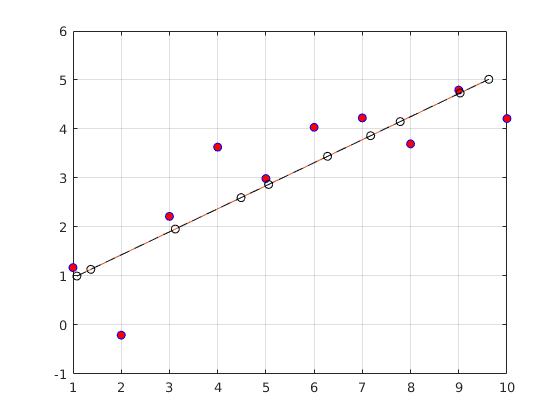

y = score*coeff'+ mean(x);

hold on
plot(y(:,1),y(:,2))
plot(y(:,1),y(:,2),'--ok')